%Loading Dataset from extracted folder on our local machine
dataset_path = 'C:\Users\Hazem Abdelaziz\Downloads\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\KITTI\City_2011_09_26_drive_0009\2011_09_26\2011_09_26_drive_0009_sync';

%Visualize stereo camera first frame (For center cameras 0: Gray & 2: RGB)
gray_image = imread(fullfile(dataset_path, 'image_00\data', '0000000000.png'));
rgb_image = imread(fullfile(dataset_path, 'image_02\data', '0000000000.png'));

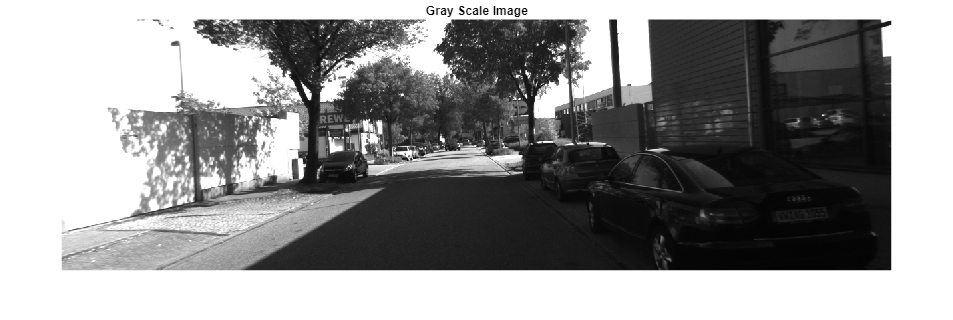

%Gray scale image visualization
figure;
imshow(gray_image);
title('Gray Scale Image');

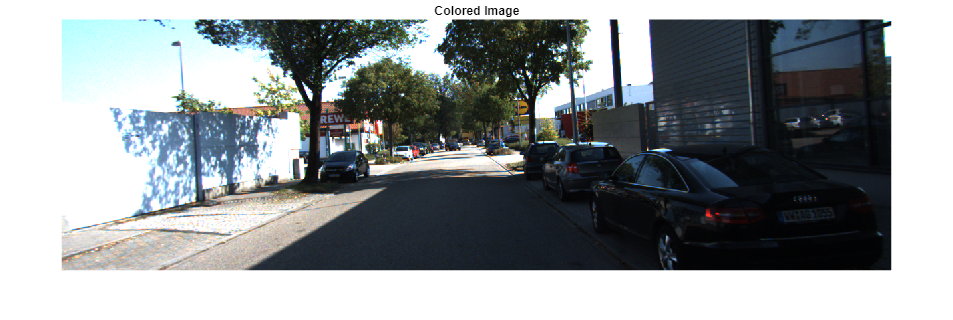

%Colored image visualization
figure;
imshow(rgb_image);
title('Colored Image');

%This section is to convert from bin file data to 
% !! This section is to be run once to avoid overwriting and saving files
%multiple times
pcdFolderPath = strcat(dataset_path, '\velodyne_points\data');
pcdFiles = dir(pcdFolderPath);
for i = 1:length(pcdFiles)
    cd(pcdFolderPath);
    filename = pcdFiles(i).name;
    if(length(filename) > 10)
        binOpen = fopen(filename, 'rb'); %Open binary in read mode
        binData = fread(binOpen, [4, inf], 'single')'; %Reading data from binary file
        fclose(binOpen);
        extension_to_remove = '.bin';
        original_str = filename;
        start_idx = strfind(original_str, extension_to_remove);
        end_idx = start_idx + length(extension_to_remove) - 1;
        modified_str = original_str;
        modified_str(start_idx:end_idx) = ''; 
        save(strcat(modified_str,'.mat'), 'binData');
    end
end

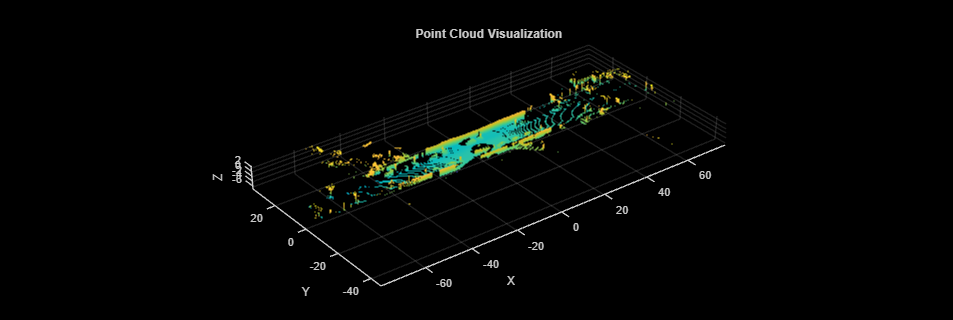

%visualize a LiDAR point cloud
point_cloud = load(fullfile(pcdFolderPath, '0000000000.mat'));
X = point_cloud.binData(:,1);
Y = point_cloud.binData(:,2);
Z = point_cloud.binData(:,3);
point_cloud_data = [X, Y, Z];
pcshow(point_cloud_data);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Point Cloud Visualization');